## Tools and the Server

An MCP server may host multiple tools. Build multi-tool servers with MCP Framework by specifying multiple MATLAB functions to `prodserver.mcp.build`. Tools cannot be added to or removed from an existing server -- servers must be rebuilt to add or remove tools.

## Build Server with Seven Tools

By default, a tool has the same name as the MATLAB function that implements the tool. Optionally, tools may be given their own names. MCP clients interact with tool names, not MATLAB function names. This code specifies new names for six of the seven tools. Even though the `snowflake` function is not getting a new name it still must have its tool name specified explicitly, since the `tool` and `fcn` inputs must be the same size.

% Tool names -- the names used to call the tool. These are the names
% reported by prodserver.mcp.list.
tool = ["twinDragon", "chaos", "snowflake", "mandelbrot", ...
    "dragonDraw", "turtleGraphic", "renderPointCloud"];

% Functions that implement the tools. Each of these names must be a
% function on MATLAB's path.
fcn = ["chaosdragon", "chaosfractal", "snowflake", ...
    "mandelbrot", "renderDragon", "drawvector", "drawpoints"];

% Build the tools into a Swiss Army knife of a server. Specify a server
% name -- otherwise the server would have the same name as the first tool
% in the tool list.
server = "Fractalizer";
ctf = prodserver.mcp.build(fcn, tool=tool, archive=server, folder="./deploy")

ctf = "S:\gecks\MCP\ClaudeCode\Examples\MultiTool\deploy\Fractalizer.ctf"

## Deploy the Server

Having successfully built the server, deploy it to an instance of MATLAB Production Server. And then query the endpoint for the list of supported tools. The response to the query provides all the information required to invoke the tool: name, description and input and output schemas.

endpoint = prodserver.mcp.deploy(ctf, "localhost", 9910)

endpoint = "http://localhost:9910/Fractalizer/mcp"

tools = prodserver.mcp.list(endpoint,"Tool")

tools = 7×1 struct array with fields:
    name
    description
    inputSchema
    outputSchema
    dollarDefs
    server


toolNames = {tools.name};
thisFolder = replace(fileparts(matlab.desktop.editor.getActive().Filename),filesep,"/");

## Create and Display TwinDragon

Used together, the `twinDragon` and `dragonDraw` tools produce an image of the twin dragon fractal. `twinDragon` generates the points of the fractal and `dragonDraw` renders those points into a JPG image. 

The automatically added wrapper functions determine the interface used to call the tool. Typically wrapper functions externalize non-scalar inputs and outputs into URL-based data sources and sinks. This prevents large data sets from passing through the large language model, which makes tools faster and cheaper. 

Use the information returned by `prodserver.mcp.list` to view the externalized interface and call the tool.

% Find the "twinDragon" tool in the list of seven tools. Look for a tool
% with the name "twinDragon".
tool = "twinDragon";
k = strcmp(tool,toolNames);

% Display the input parameters. There are two: N and dragonURL. The
% structure value of each describes the type and purpose of the input.
tools(k).inputSchema.properties

ans = struct with fields:
            N: [1×1 struct]
    dragonURL: [1×1 struct]


% N is a number specifying how many points the twin dragon fractal will
% contain.
tools(k).inputSchema.properties.N

ans = struct with fields:
           type: 'number'
    description: 'Number of points in the resulting fractal.'


% dragonURL is an output location, a URL which must be capable of receiving
% an Nx2 matrix of floating point numbers.
tools(k).inputSchema.properties.dragonURL

ans = struct with fields:
           type: 'string'
    description: {7×1 cell}


% Setup to generate a fractal with 200,000 points. Return the points in a 
% MAT-file, TwinDragonXY.mat, in the same directory as this file.
N = 200000;
dragonXY = fullfile(thisFolder,"TwinDragonXY.mat");
dragonURL = "file:" + replace(dragonXY,filesep,"/");

% Call the tool using the MCP protocol and check for success: the tool
% should create the MAT-file.
prodserver.mcp.call(endpoint,tool,N,dragonURL=dragonURL);
success = exist(dragonXY,"file") == 2

success = logical
   1


% Use the information returned by prodserver.mcp.list to determine how to
% call the dragonDraw tool. Note the location of the JPG result is specified 
% by file path rather than by a URL. That's because the JPG location is a
% scalar string input to the original function and thus not subject to an
% externalizing transformation by the wrapper function.
tool = "dragonDraw";
k = strcmp(tool,toolNames);
tools(k).inputSchema.properties

ans = struct with fields:
    dragonURL: [1×1 struct]
       color1: [1×1 struct]
       color2: [1×1 struct]
          jpg: [1×1 struct]
        szURL: [1×1 struct]


% Setup to call a second tool, dragonDraw, to render the points of the
% fractal into a JPG image. 
jpg = fullfile(thisFolder,"TwinDragonImage.jpg");
color1 = "#FF0000";   % Red
color2 = "#0000FF";   % Blue
dragonSize = fullfile(thisFolder,"TwinDragonSize.mat");
dragonSizeURL = "file:" + replace(dragonXY,filesep,"/");

% Call the dragonDraw tool using the MCP protocol. Test for success by
% looking for the generated JPG file.
prodserver.mcp.call(endpoint,tool,dragonURL,color1,color2,jpg,szURL=dragonSizeURL);
success = exist(jpg,"file") == 2

success = logical
   1


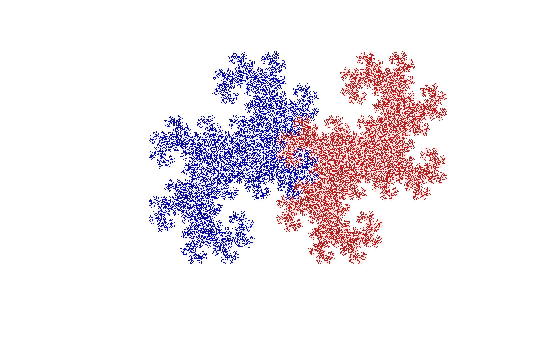

% Display the generated image
figure
img = imread(jpg);
imshow(img);